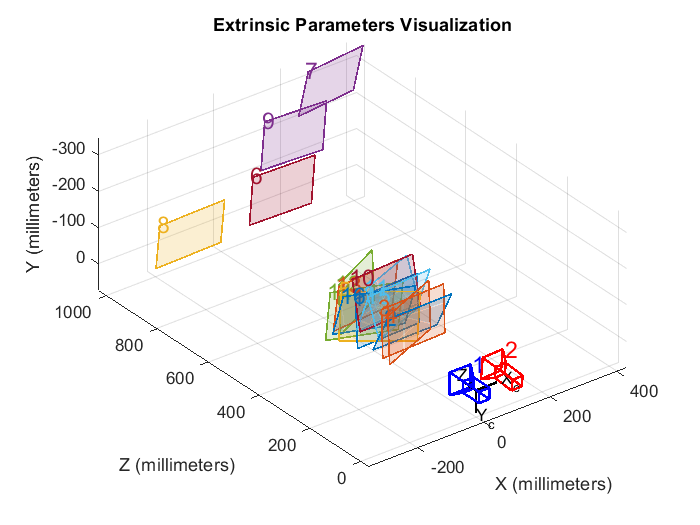

clc;
clear all;

load('calibration_support.mat');


% Visualize camera extrinsics.
showExtrinsics(stereoParams);

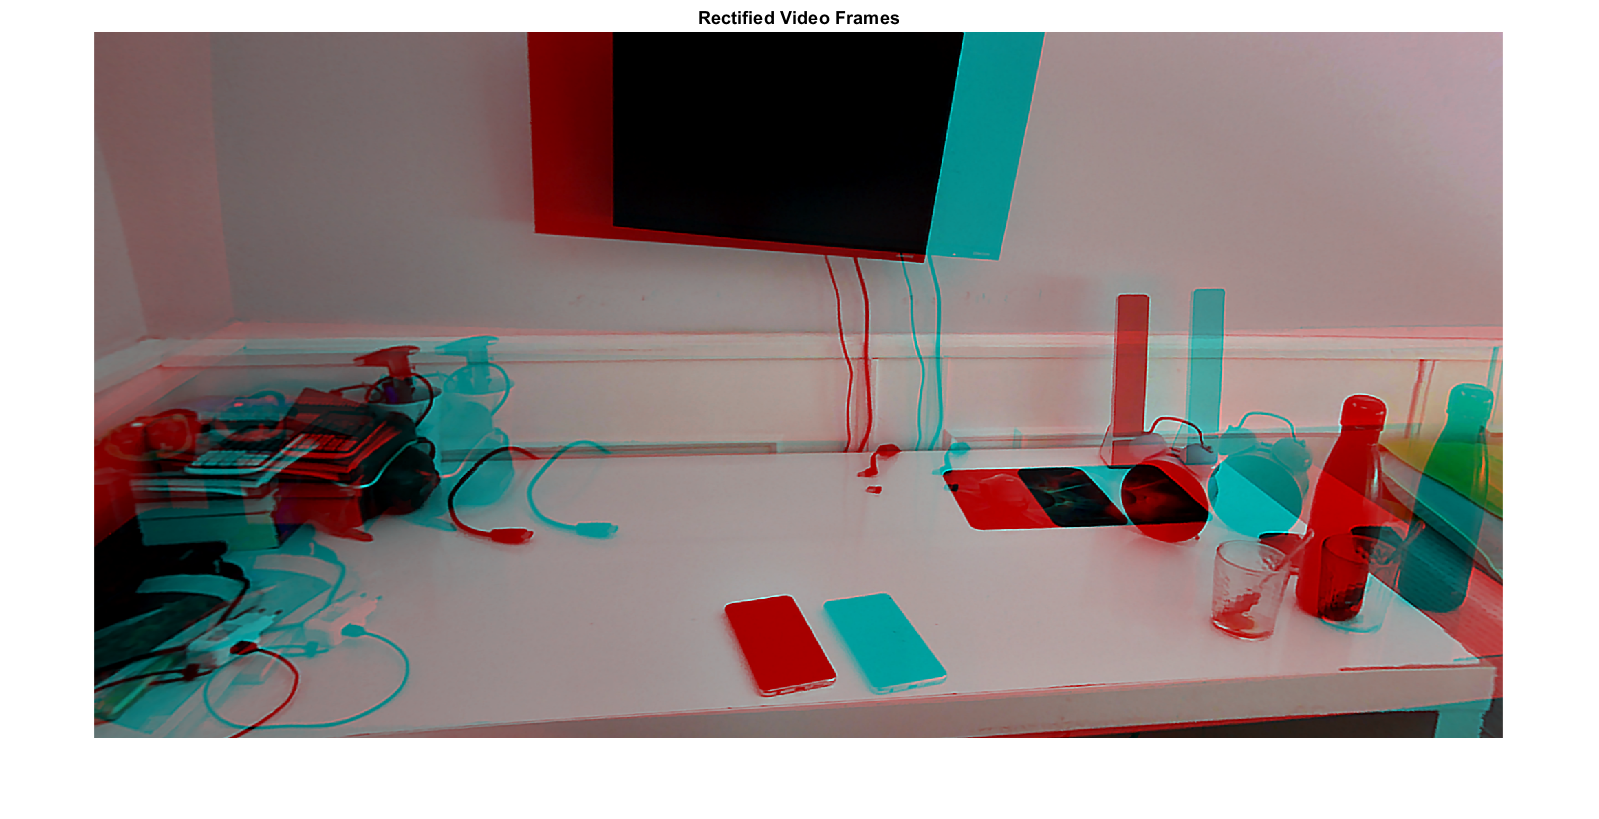

frameLeft = imread('Scripts/images/left_12.png'); 
frameRight = imread('Scripts/images/right_12.png');

[frameLeftRect, frameRightRect] = rectifyStereoImages(frameLeft, frameRight, stereoParams);

figure;
imshow(stereoAnaglyph(frameLeftRect, frameRightRect));
title('Rectified Video Frames');

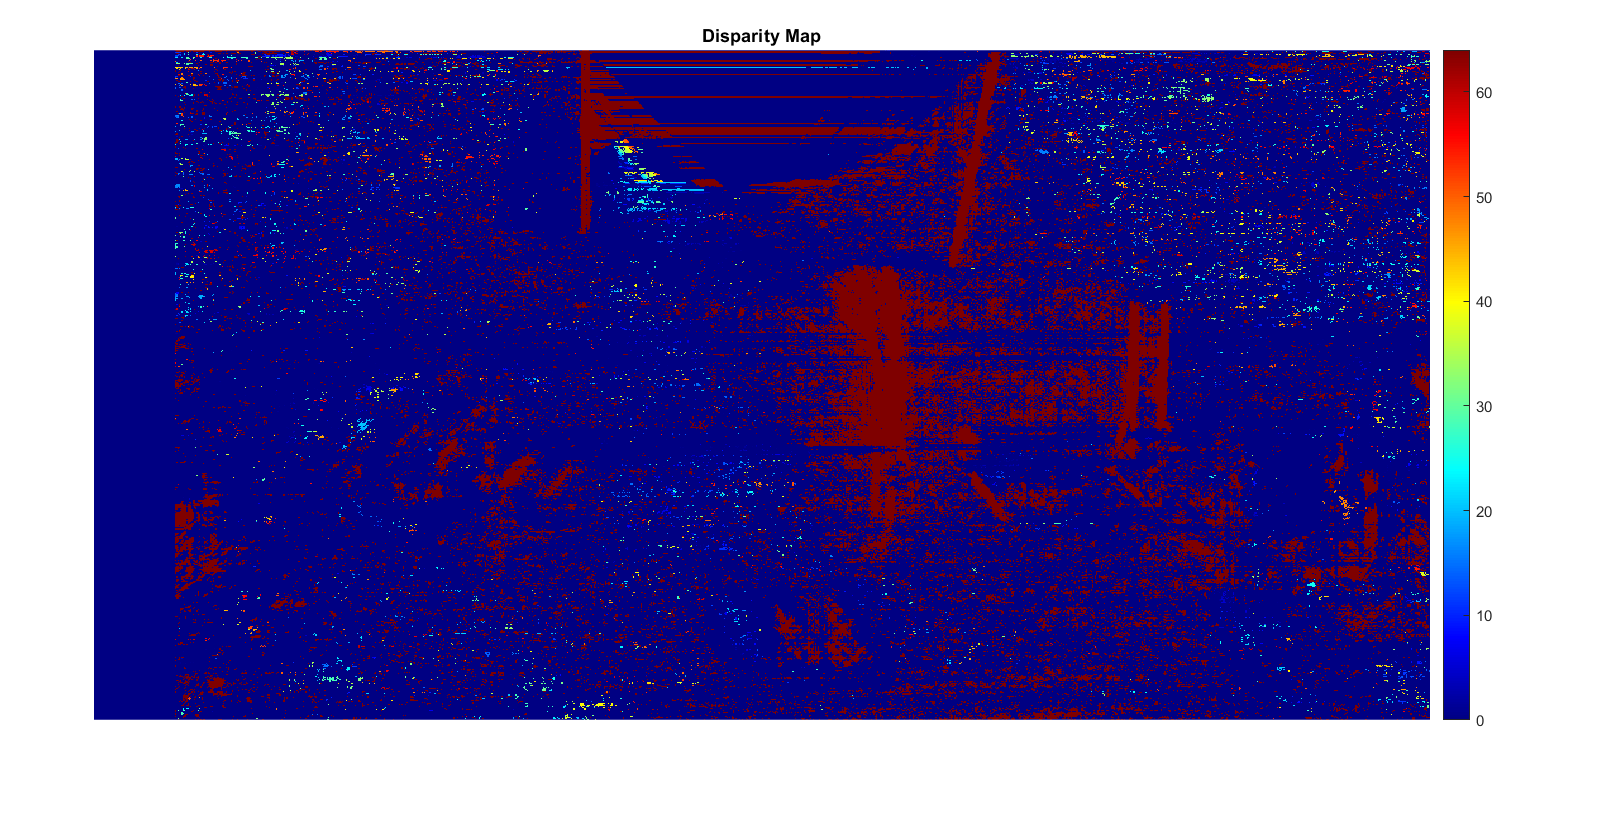

frameLeftGray  = rgb2gray(frameLeftRect);
frameRightGray = rgb2gray(frameRightRect);
    
disparityMap = disparitySGM(frameLeftGray, frameRightGray);
figure;
imshow(disparityMap, [0, 64]);
title('Disparity Map');
colormap jet
colorbar

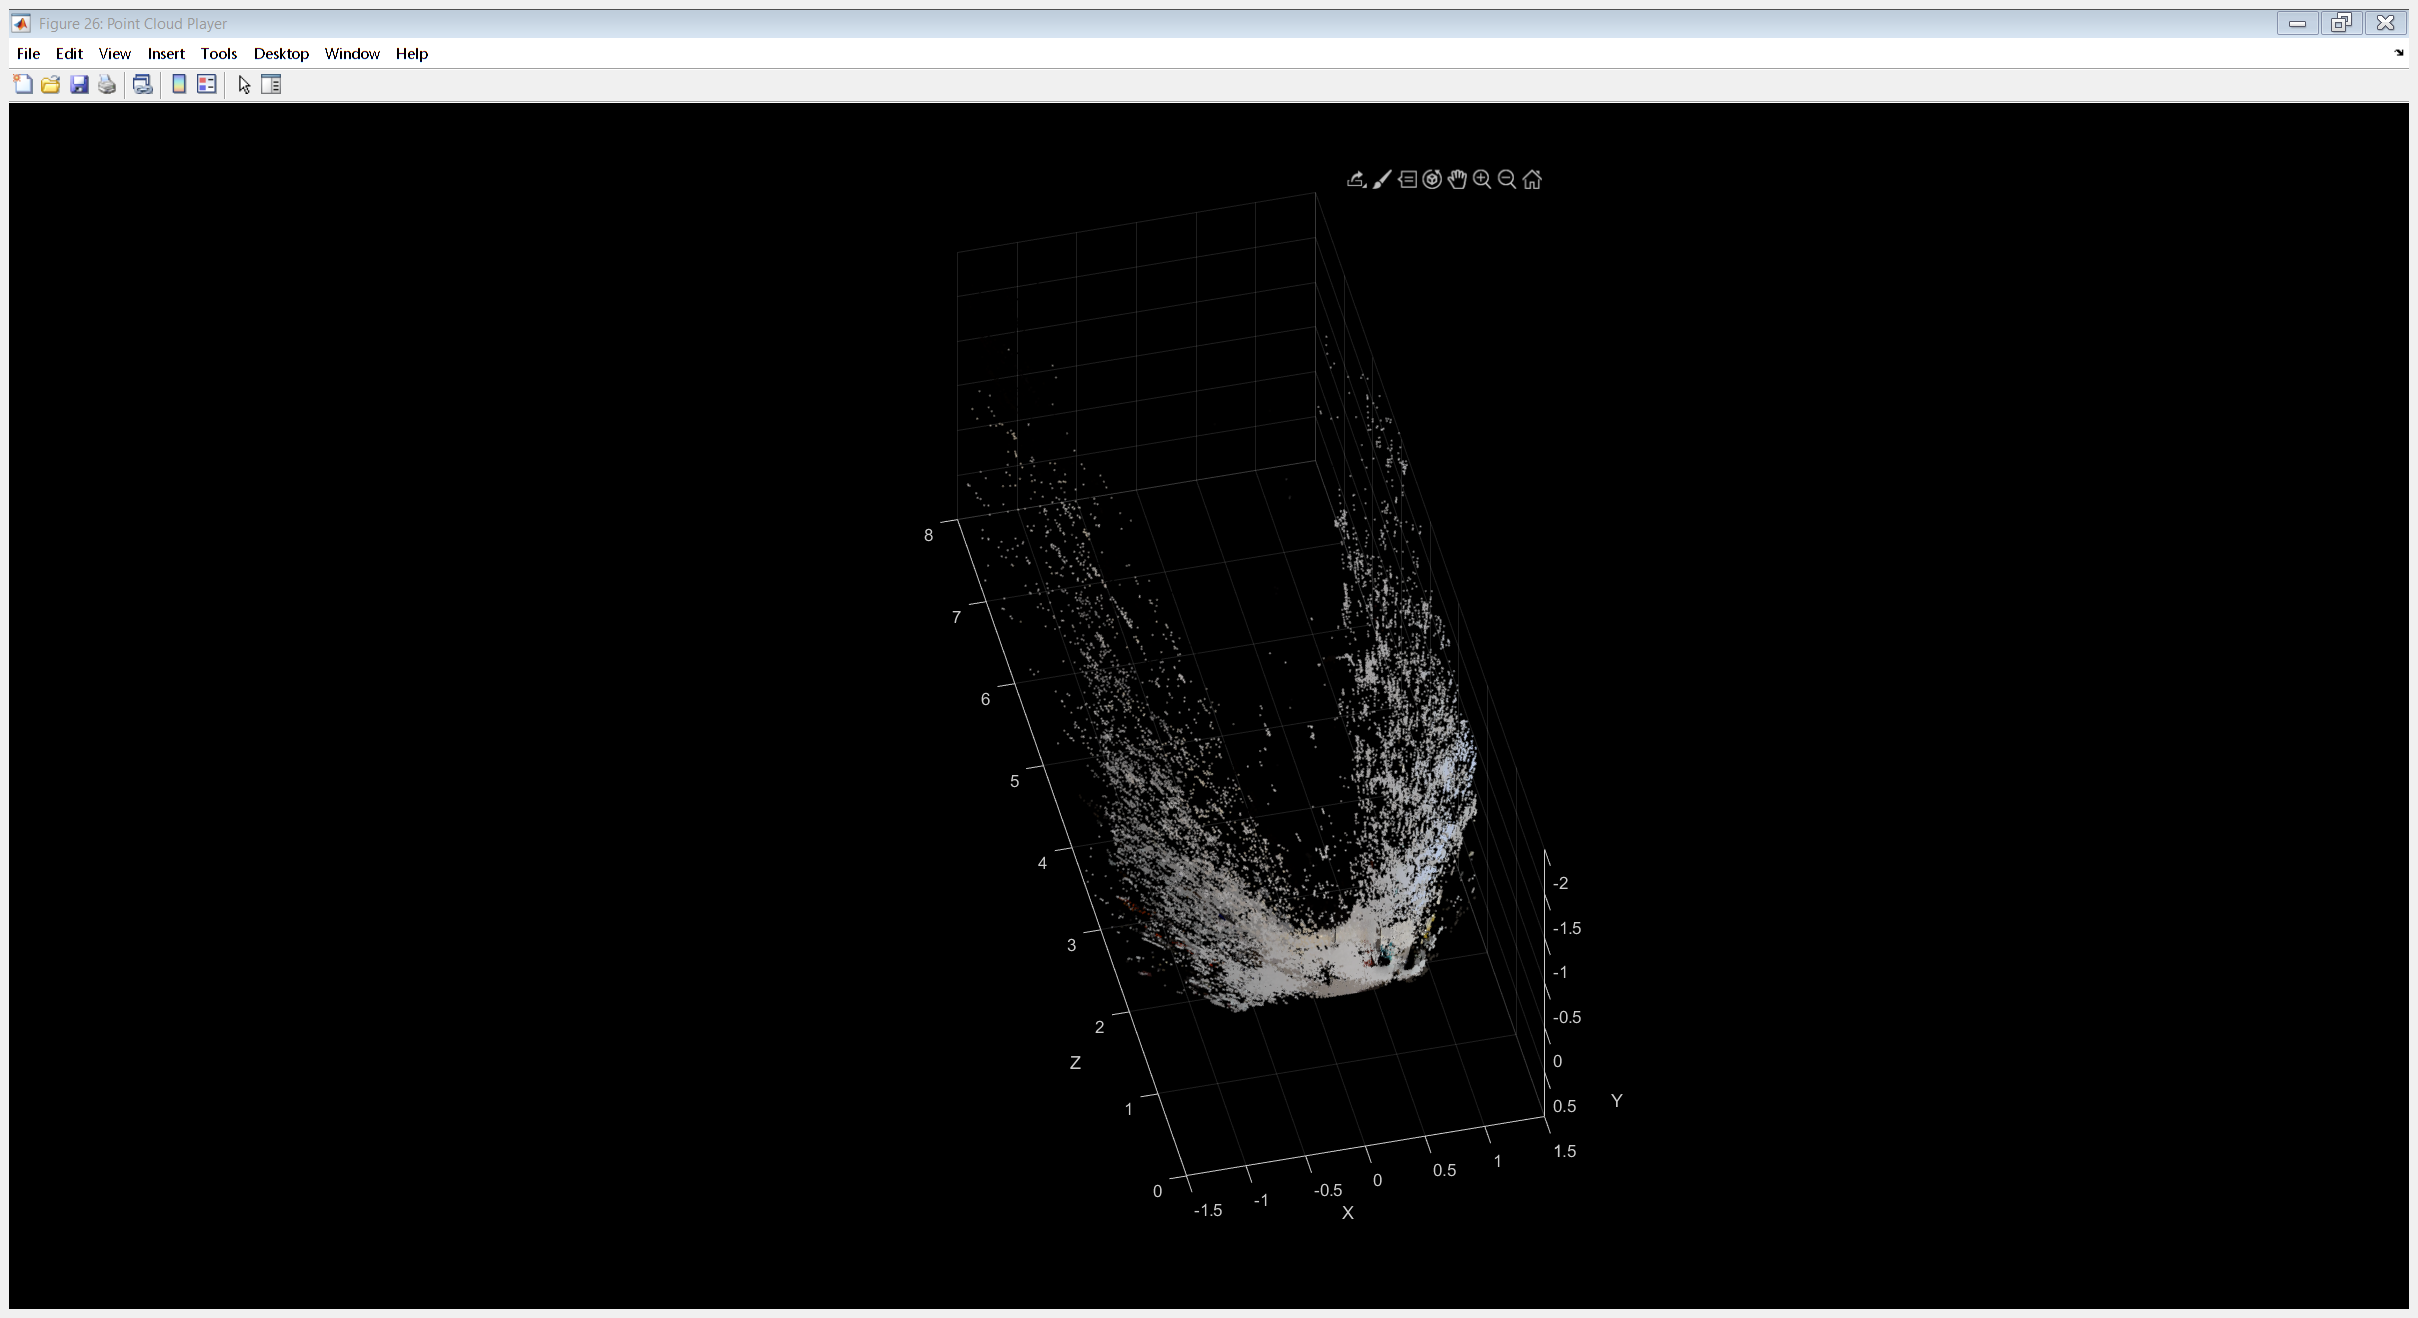

points3D = reconstructScene(disparityMap, stereoParams);

% Convert to meters and create a pointCloud object
points3D = points3D ./ 1000;
ptCloud = pointCloud(points3D, 'Color', frameLeftRect);

% Create a streaming point cloud viewer
player3D = pcplayer([-1.5, 1.5], [-2, 1], [0, 8], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(player3D, ptCloud);

pcwrite(ptCloud,'pasillo.ply')